# Off-board charger for electric vehicles

## **Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

## Introduction

An **off-board charger** is a type of battery charging system designed to recharge electric vehicles (EVs) or other battery-powered systems. Unlike on-board chargers, which are integrated into the vehicle, off-board chargers are standalone devices. These chargers are commonly found at charging stations or in facilities where high-powered and rapid charging is needed.

Off-board chargers are particularly suited for scenarios requiring high charging power or where space constraints in the vehicle make it impractical to include a high-capacity charging system. They can deliver direct current (DC) power directly to the battery, bypassing the vehicle’s onboard charger. This approach enables faster charging and greater efficiency compared to alternating current (AC) charging, which requires conversion within the vehicle.

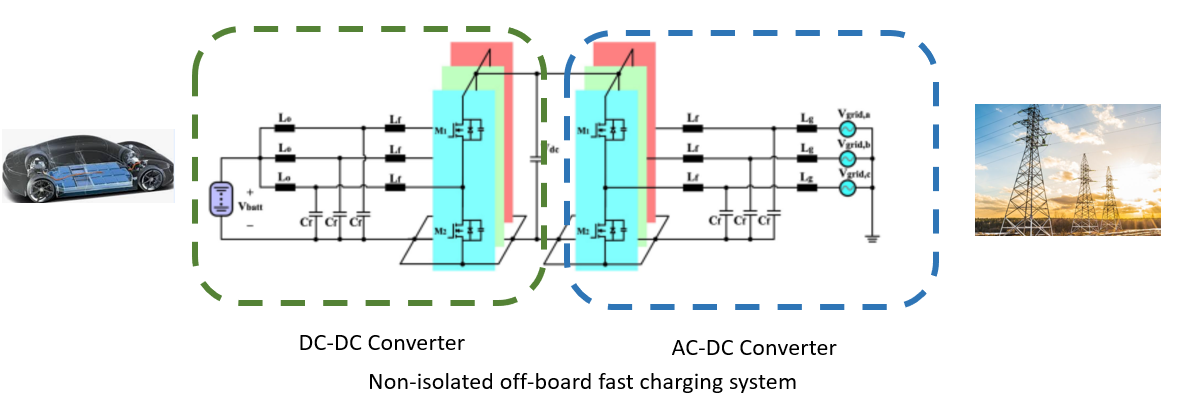 

## Charging the battery

There are two major stages when charging the battery:** constant current** charging and** constant voltage** charging.

- **Constant Current (CC) Stage**:

- During the initial phase, the off-board charger supplies a constant current (e.g., 20 A as shown in the graph) to the battery while the voltage gradually increases.

- This stage is used to rapidly charge the battery up to around 70-80% of its capacity.

- The main goal here is to quickly reach a target voltage while ensuring safe thermal conditions.

         2. **Constant Voltage (CV) Stage**:

- Once the battery reaches its target voltage (e.g., 115 V), the charging mode switches to **Constant Voltage**. Here, the voltage is held steady, while the current gradually decreases as the battery approaches full charge.

- This stage is crucial for topping off the remaining charge to reach 100% charge without overcharging, which could degrade the battery over time.

- The gradual reduction of current protects the battery cells, extending their lifespan by preventing over-voltage and thermal stress.

This dual-phase approach optimizes charging speed, efficiency, and battery health.

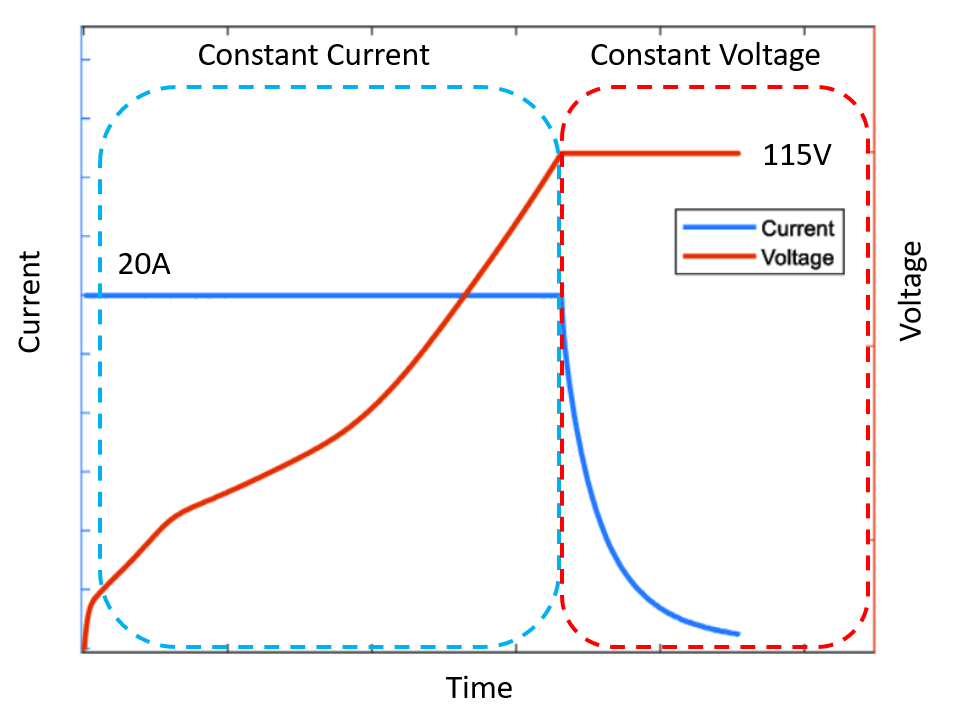

Another important parameter of the battery is the **state of charge** (SOC) which is a measure of the battery's charge as a percent of full charge. In this model, the SOC is used to monitor the charging process between the different charging stages. The SOC is calculated as the following:


$$\[ SOC = 100 \left( 1 - \frac{1}{Q} \int_0^t i(t) \, dt \right) \]$$


In this model, a fast charger system is designed where a **high level** (line-line voltage of 480 V) AC source is used to charge the battery. And the charging current (150 A) and power are much higher than in an on-board charger.

## Circuit

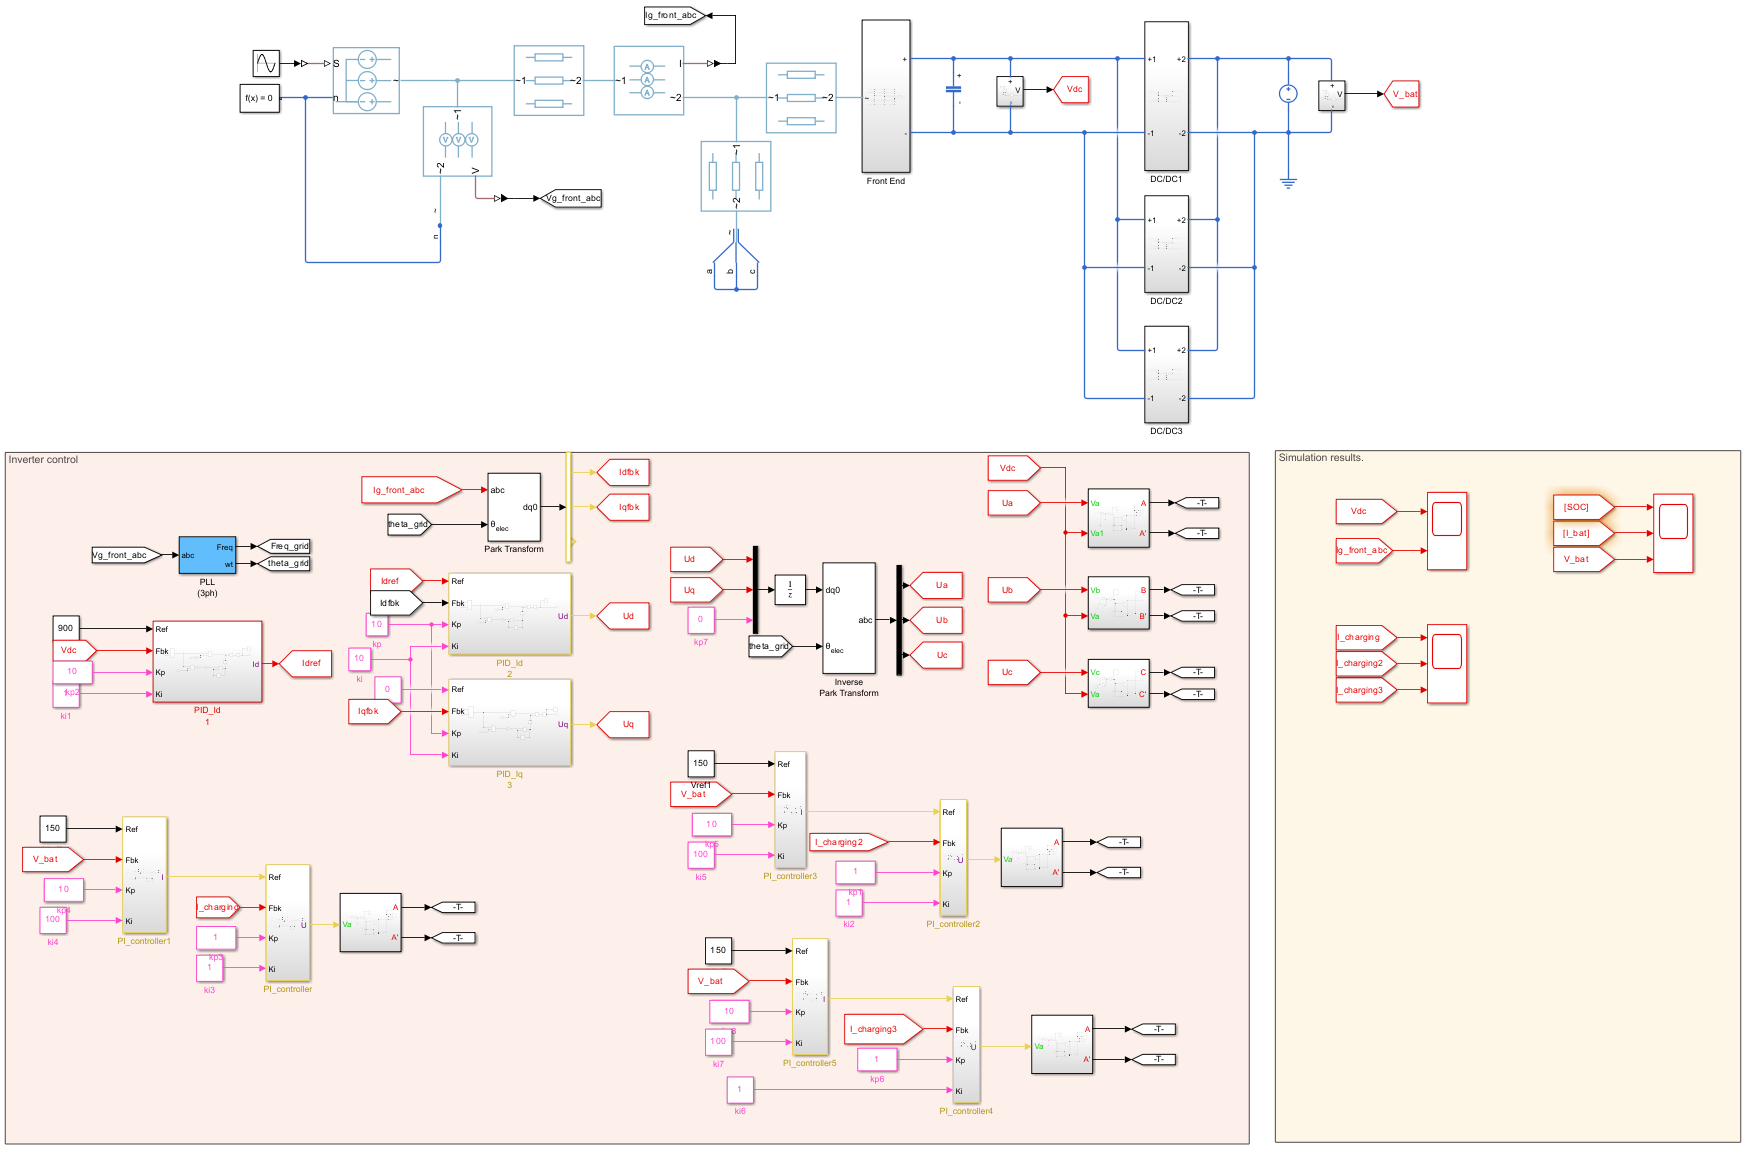

Click the button below to open the model.

 
open_system('model/offboard_SSC_simscape.slx')
if ~exist('V_ref','var')
    V_ref = 900;  
end

Select from the menu below to learn more about different parts of the model.

switchRectifier("No Selection");

In this section, another** isolated **off-board charger model is also provided. 

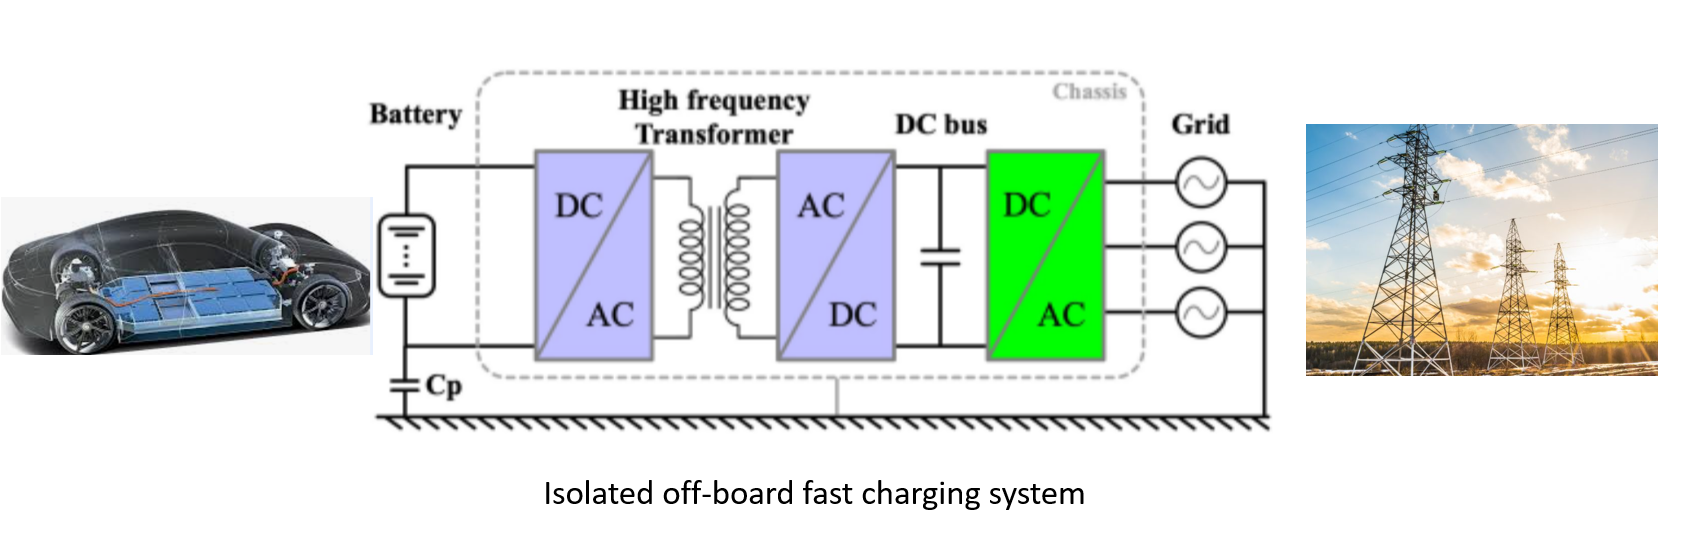

[Check the isolated model by clicking this link](matlab:open('sublivescript\isolated_start.mlx'))

### Connect to the Grid

For simulation purposes, to ensure the **stability** and **quality** of the power grid, the only requirement for the inverter’s AC output is that its **frequency **matches the grid’s frequency and **phase angle**. A Phase-Locked Loop (PLL) strategy is used to measure grid frequency. At this stage, we do not need to examine the internal principles or operation of the PLL.

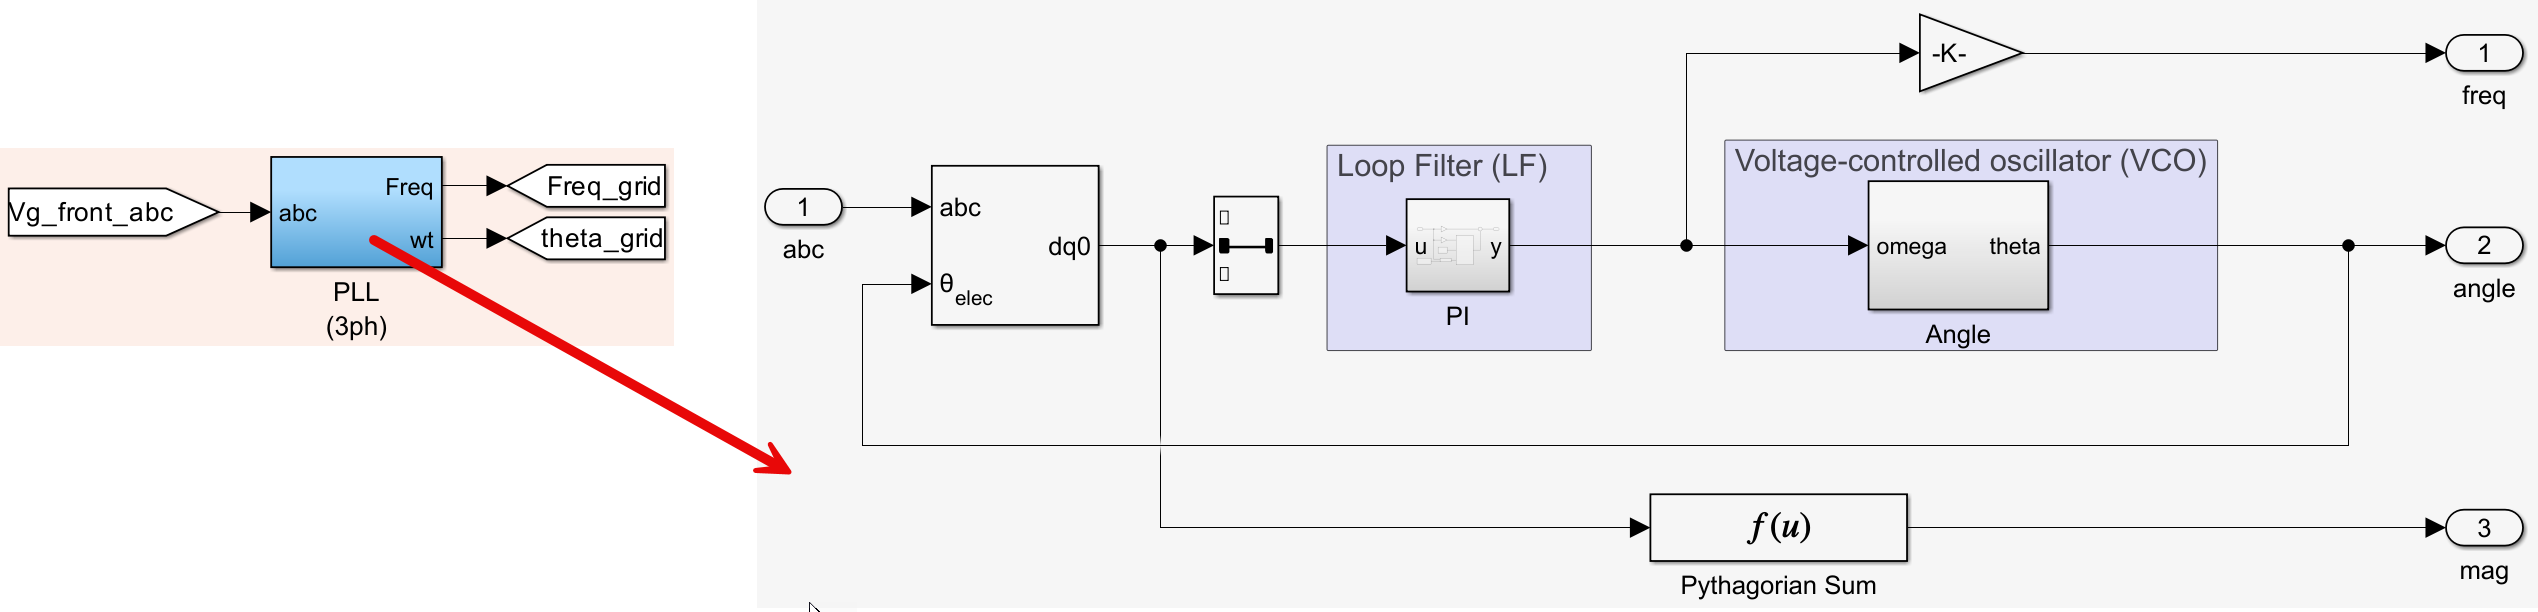

## Control Algorithm

Generally, the control algorithm includes three parts: 

- Charging current/voltage control 

- Inverter and DC bus control

- Second-Order Generalized Integrator (SOGI)

 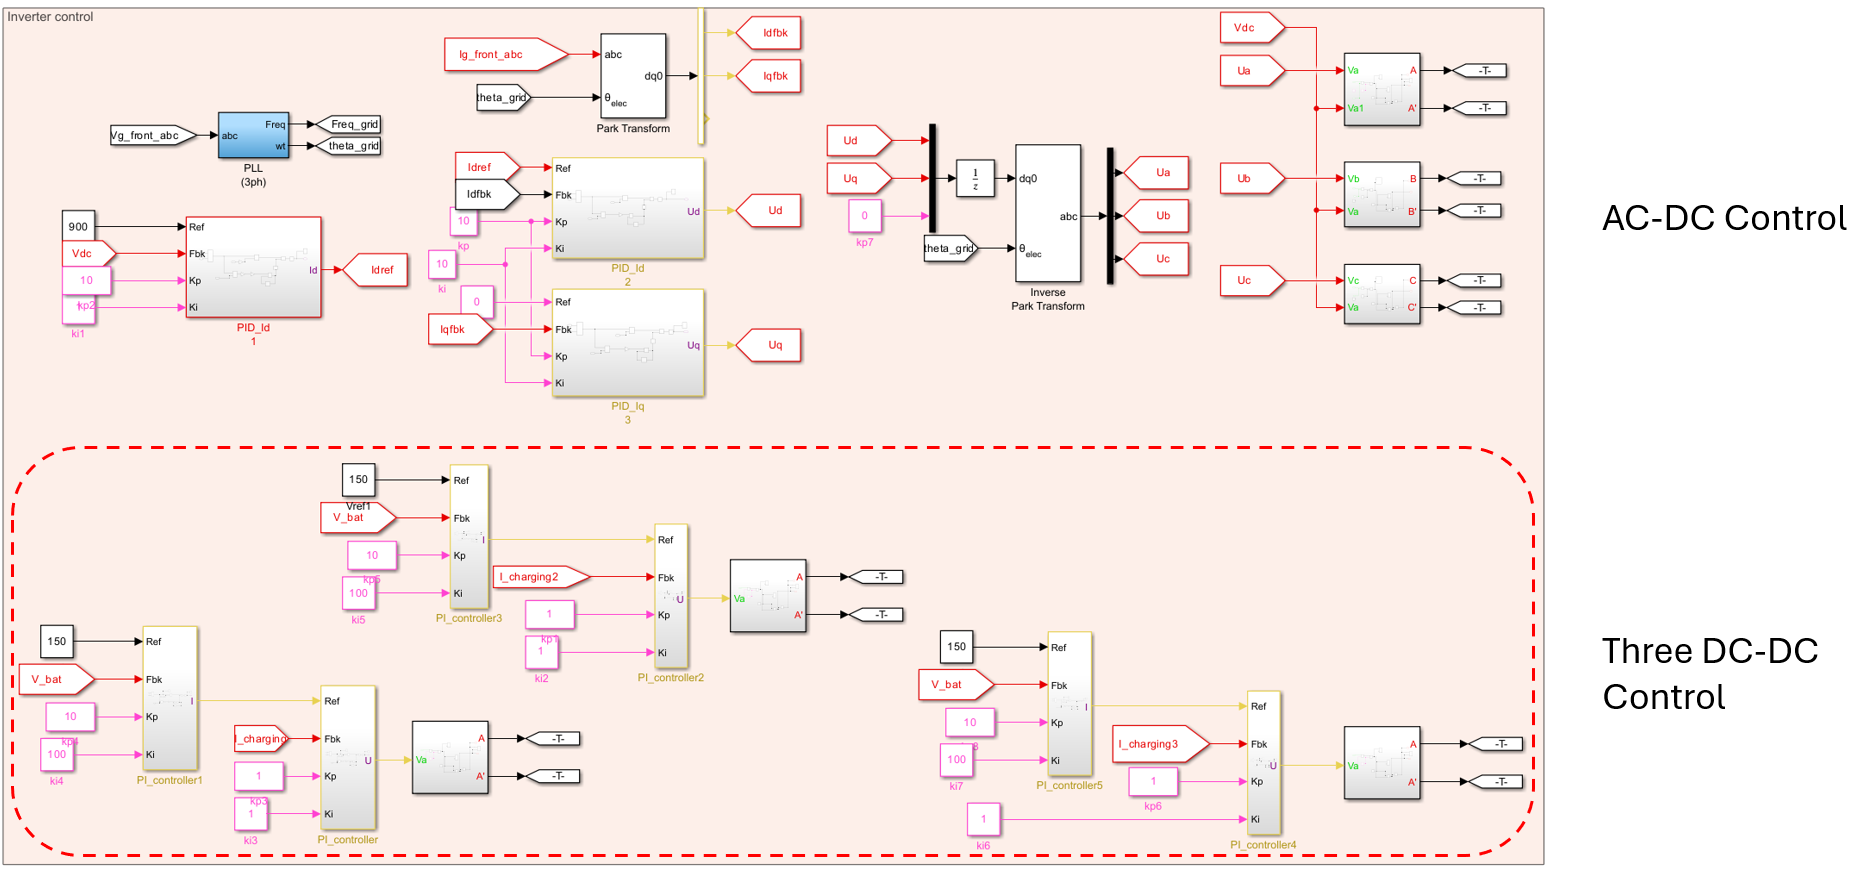

### Charging current and voltage control

The control algorithm is designed for two stages, **constant current** stage and **constant voltage** stage. 

For each DC-DC converter, two PI controllers are used to control the charging voltage and charging current. In this model, the charging voltage is set to 150 V and the charging current to 50 A for each converter.

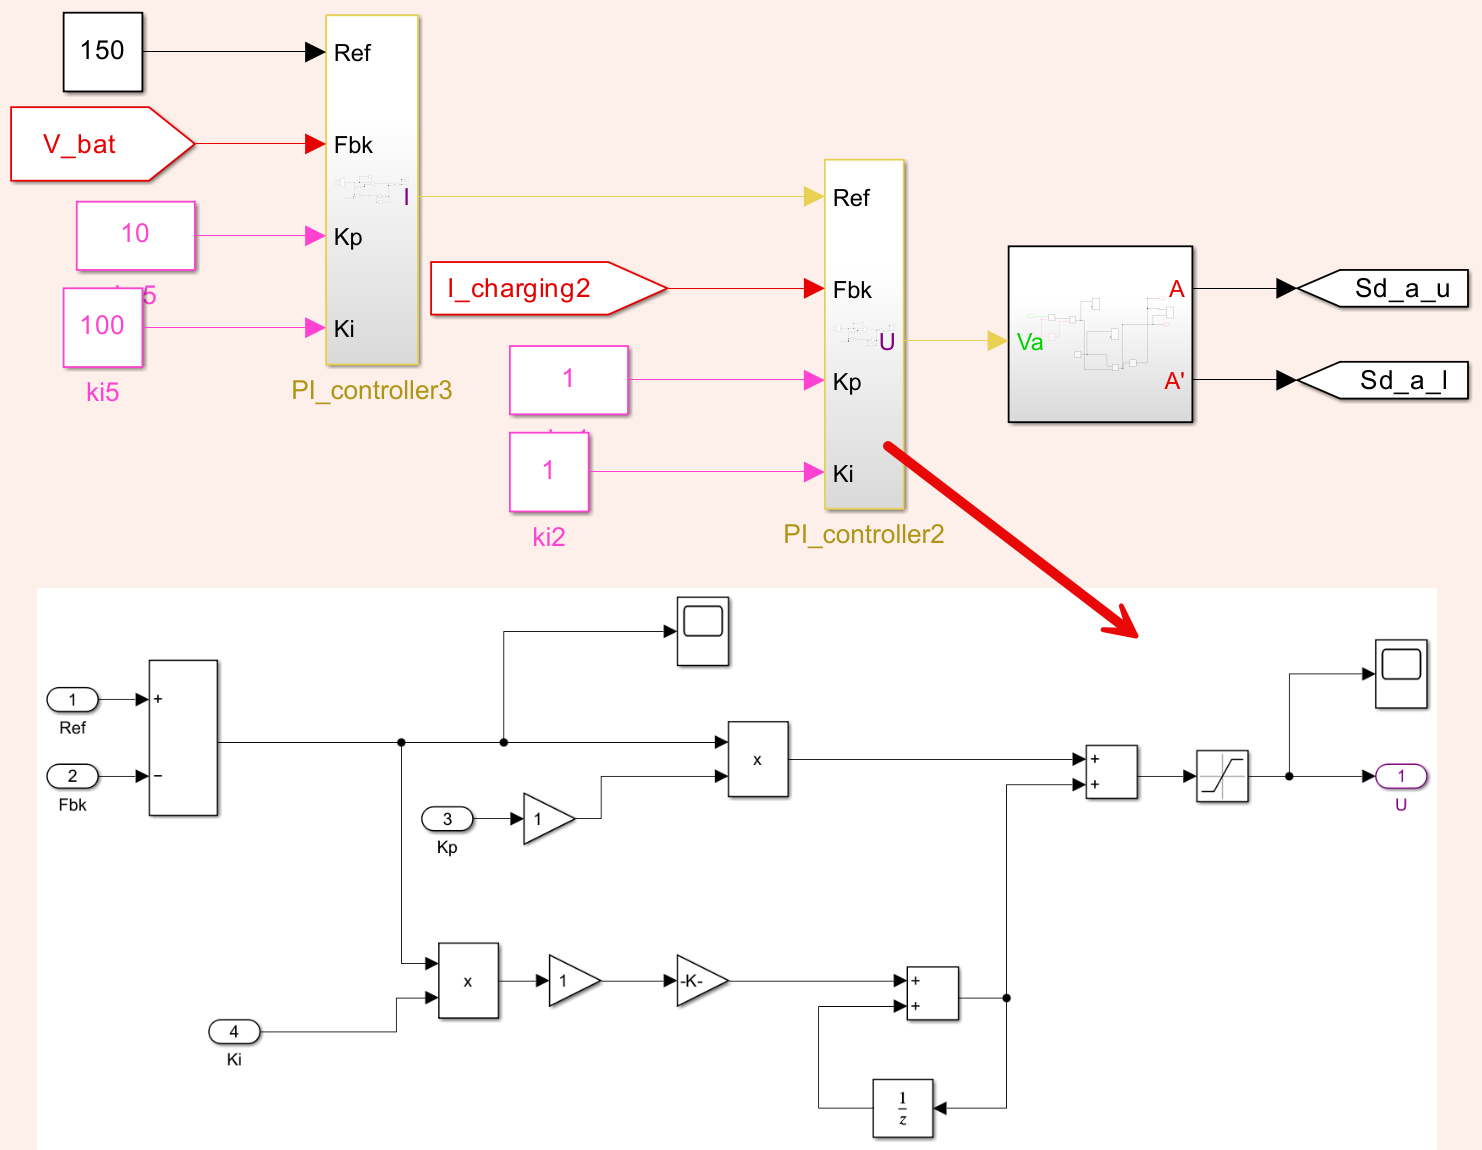

**Constant current charging stage configuration.**

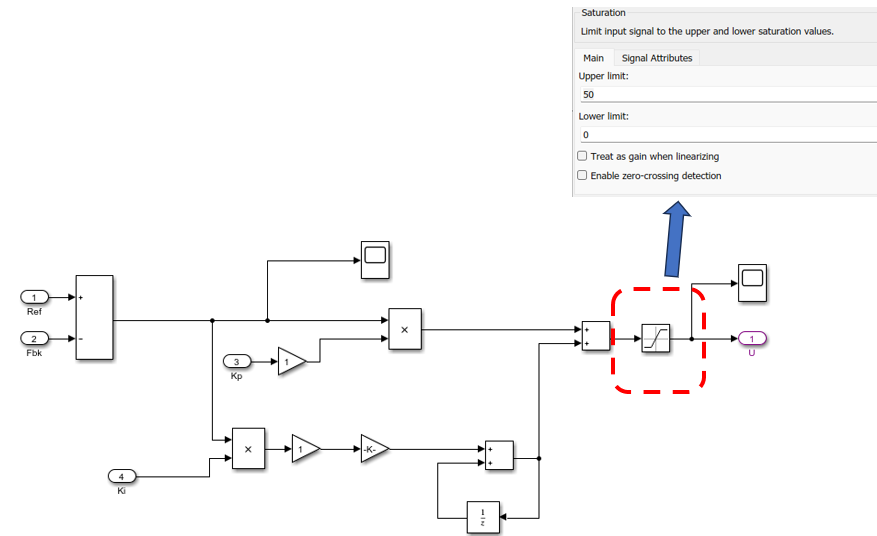

### Inverter and DC Bus Control

The inverter control includes two major parts: **current and voltage controller **and **duty cycle generation **. 

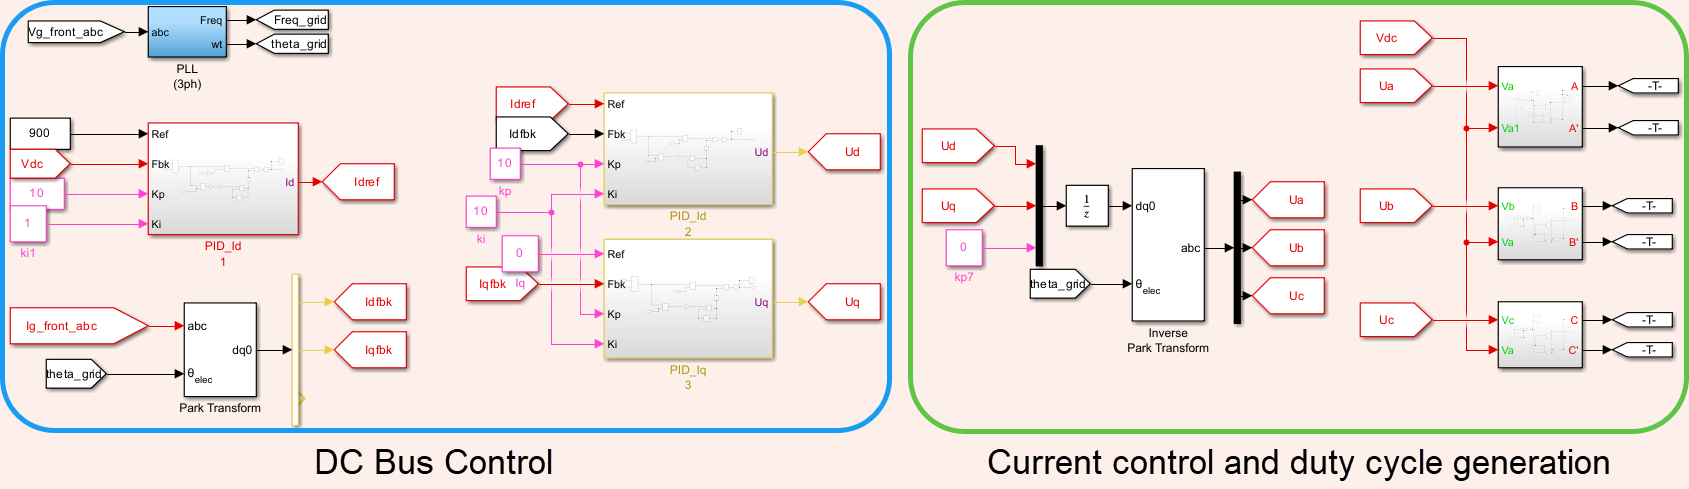

Select from the menu below to learn more about different parts of this controller.

controller("No Selection")

Vdc is the DC voltage output. Changing its reference value will greatly affect the output voltage and output power. The default value is set to 900V.

Use the slider below to change V_ref parameter in the model and observe how the output changes.

V_ref=900
 
run_offboard(V_ref)

## Analyzing the results

Now, go to the model and run it, if you haven't do so already. After the simulation is complete **(this may take a few minutes)**, open the scopes to see the results. 

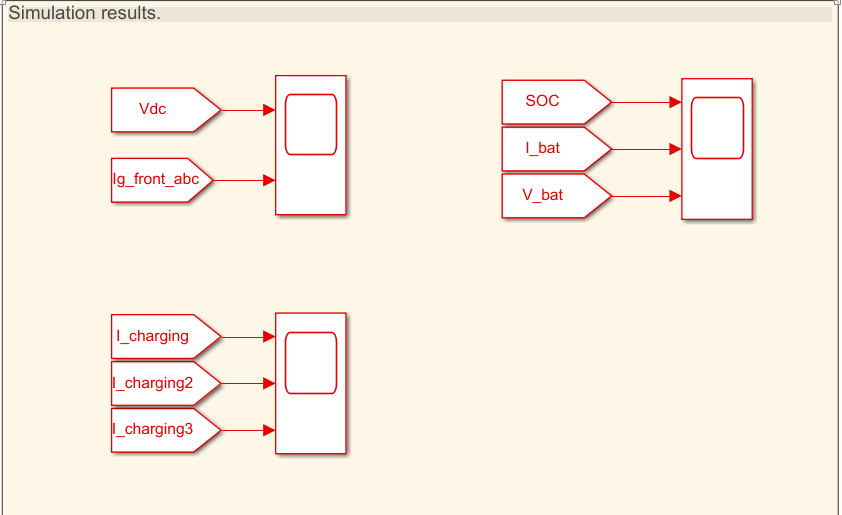

In this model, you are also encouraged to change the** initial SOC** of the battery to find the **constant current** and **constant voltage** stages.

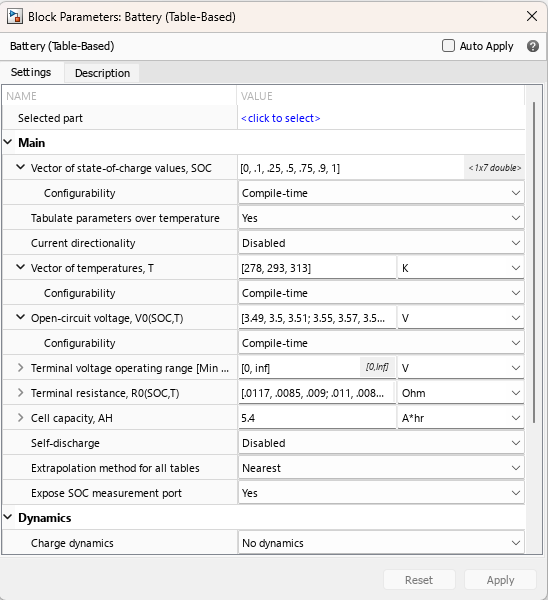

With the menu below, you can check reference simulation results provided for your convenience.

result("No Selection")

## Exercise

 **Exercise 1. What is the correct conversion sequence from power grid to battery (off-board charging)?**

exerciseSol1(...
     false, ...
   false);
 

 **Exercise 2. Why there are three DC-DC converters in this model?**

exerciseSol2(...
     false, ...
   false,...
  false);
 

 **Exercise 3 Check the simulation result of the model and try to increase the charging current, if the charging current is too high what might happen?**

exerciseSol3(...
     false, ...
   false,...
   false);
 

## Conclusion

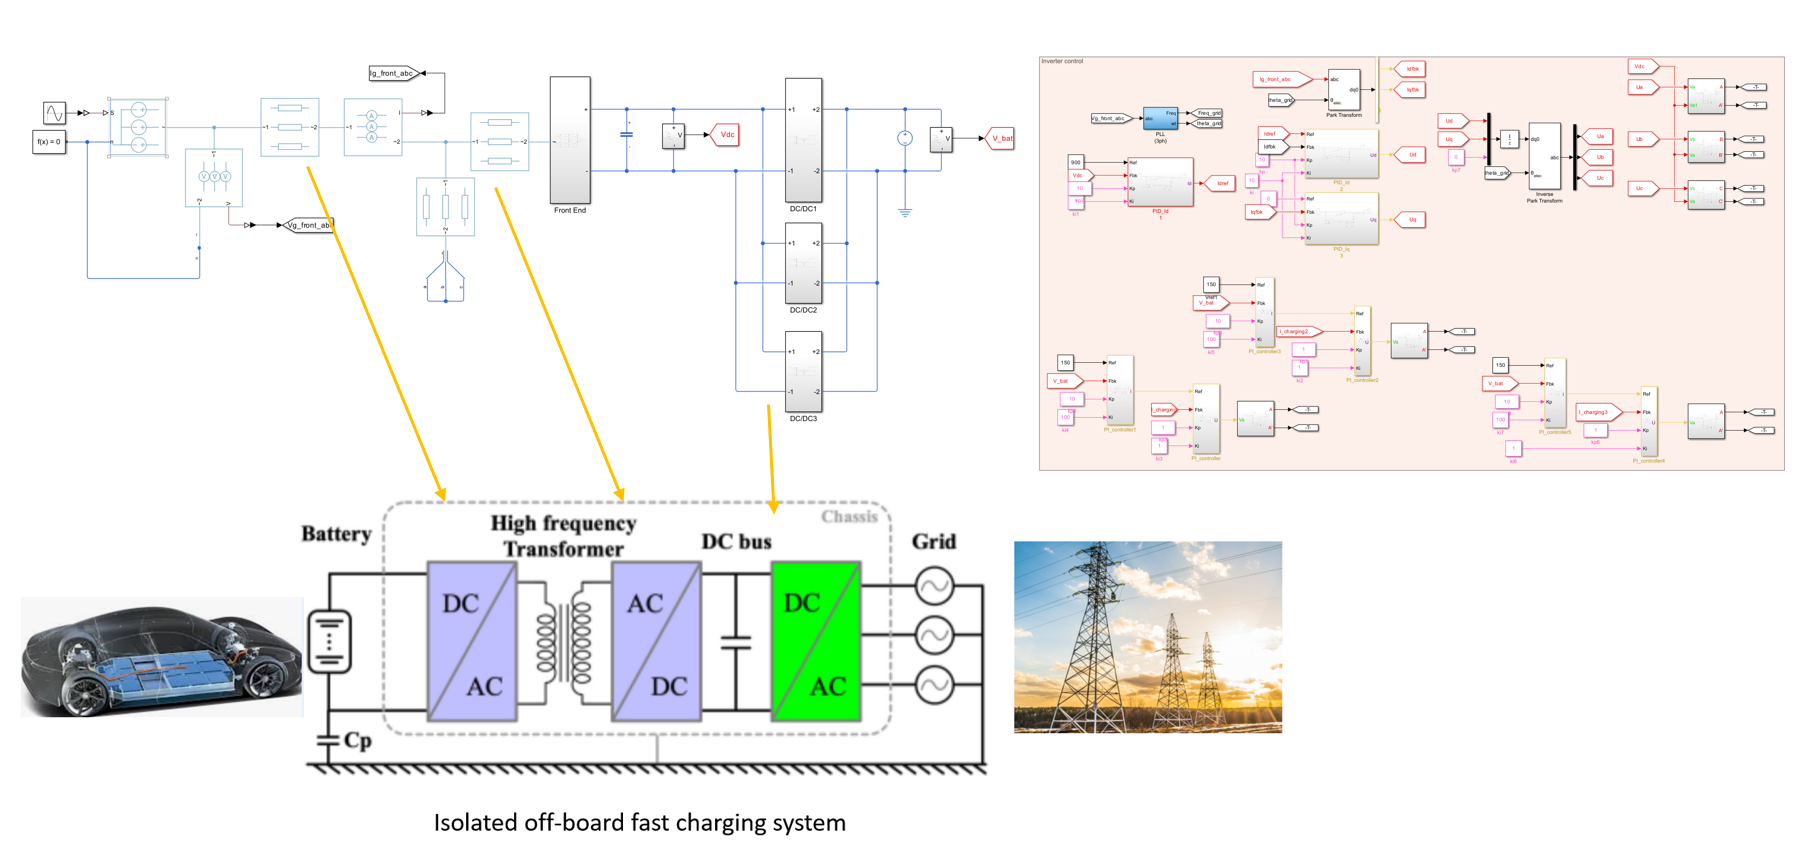

This interactive Live Script provides a comprehensive simulation framework for analyzing the behavior of a high-power off-board battery charging system. By integrating model-based simulation with real-time parameter tuning through sliders and buttons, users can explore key characteristics of the charging process under varying control conditions.

function switchRectifier(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "battery" "Grid" "Threedc"])}
end
clf;
if opt == "No Selection"
else
    if opt == "battery"
        rect = imread("Images/battery.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Grid"
        rect = imread("Images/grid.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Threedc"
        rect = imread("Images/LLC.png");
        imshow(rect, 'Interpolation', 'bilinear');
  
    end
end
end


function controller(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "DCbus control" "Inverter control" "SPWM"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Inverter control"
        rect = imread("Images/controller.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "SPWM"
        rect = imread("Images/SPWM.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "DCbus control"
        rect = imread("Images/dcbus.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function result(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Grid" "Battery" "Converter"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Grid"
        rect = imread("Images/result1.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Battery"
        rect = imread("Images/Result2.png");
        imshow(rect,"Interpolation","bilinear");
     elseif opt == "Converter"
        rect = imread("Images/Result3.png");
        imshow(rect,"Interpolation","bilinear");
        
    end
end
end





function exerciseSol1(A,B)
  
    arguments
        A (1,1) logical
        B (1,1) logical
        
    end

    if ~any([A B])
        warning("Please select an answer!")
    elseif A && B
        warning("Please select only one answer");
    elseif A
        disp("Correct!")
    else 
        warning("Incorrect. Please review the circuit section again.")
    end
end

function exerciseSol2(A,B,C)
 
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
        
    end

    if ~any([A B C])
        warning("Please select an answer!")
    elseif A+B+C > 1
        warning("Please select only one answer")
    elseif B
        disp("Correct!")
    else 
        warning("Incorrect. Please check the control section again")
    end
end
function exerciseSol3(A,B,C)
 
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
    end

    if ~any([A B C])
        warning("Please select an answer!")
    elseif A+B+C > 1
        warning("Please select only one answer")
    elseif C
        disp("Correct!")
    else 
        warning("Incorrect.")
    end
end

% function showpic1(A)
% 
%     arguments
%         A (1,1) logical   
%     end
%     clf;
%     if A
%         rect = imread("Images/CC.png");
%         imshow(rect,'Interpolation',"bilinear");
%     else 
%     end
% end
function showpic2(A)
   
    arguments
        A (1,1) logical   
    end
    clf;
    if A
        rect = imread("Images/CV.png");
        imshow(rect,'Interpolation',"bilinear");
    else 
    end
end



function run_offboard(V_ref)

    function [t, y] = extract_sig_data(simOut, name)
        if isprop(simOut, name)
            raw = simOut.(name);
        else
            raw = simOut.get(name);
        end
        
        if isa(raw, 'timeseries') 
            t = raw.Time;
            y = squeeze(raw.Data);
        elseif isstruct(raw) && isfield(raw, 'time') 
            t = raw.time;
            y = squeeze(raw.signals.values);
        else
            error(['Signal "' name '" format not supported. Please set To Workspace block to "Structure with Time" or "Timeseries".']);
        end
    end

   assignin('base','V_ref',V_ref);       
    wState = warning('off', 'all');
    try
        simOut = sim('model/offboard_SSC_simscape.slx'); 
    catch ME
        warning(wState); 
        rethrow(ME);
    end
    warning(wState); 
    out = simOut;

    [time_vdc, vdc_val] = extract_sig_data(out, 'Vdc');
    [time_ibat, ibat_val] = extract_sig_data(out, 'I_bat');

    len = min(length(vdc_val), length(ibat_val));
    
    vdc_aligned = vdc_val(1:len);
    ibat_aligned = ibat_val(1:len);
    time_aligned = time_vdc(1:len);
    pdc_val  = vdc_aligned .* ibat_aligned;

    
    fig = figure('Position',[100,100,1000,500]); 
    subplot(1,2,1);
    yyaxis left
    plot(time_aligned, vdc_aligned, 'LineWidth', 1.5); ylabel('V_{dc} (V)');
    yyaxis right
    plot(time_aligned, ibat_aligned,'LineWidth', 1.5); ylabel('I_{bat} (A)');
    xlabel('Time (s)'); title('DC Output Voltage and Battery Current');
    legend('V_{dc}','I_{bat}','Location','best'); grid on;

    subplot(1,2,2);
    plot(time_aligned, pdc_val,'LineWidth',1.5);
    title('DC Output Power'); xlabel('Time (s)'); ylabel('Power (W)'); grid on;
end